clear
clear all
clc;

load('data.mat');

%% Variables and constants
%%Constants
p_atm = 101.325 * 10^3; %% pascal
Taf = 300; %% kelvin

yi =  1.3;
yc = 1.25;
ye = 1.48;
R = 287.05; %%287.05; %% gas constant of air (J/kg * Kelvin)
phi = 1;
pressure_offset = 5325; %% pascal
CBF = 0.95; 
AFR = 14.7; 
Qhv = 44.4*10^6; %% j/kg
cv = R/(1-yc); %% J/kgk
a = 5;
m = 2;
error = inf;
tolerance = 1;
%%Per Engine
bore = 84/1000; %% mm
d_in_valve = 33/1000; %% mm
d_out_valve = 30.5/1000; %% mm
rpm = 2200;
dt = 1/(rpm *2*pi/60)*(pi / 180);
Cd = 0.7; %% check unit
Ati = 0.785398*(d_in_valve)^2; 
Ate = 0.785398*(d_out_valve)^2;
Pe = p_atm ;%+ pressure_offset; %% pascal
Pi = p_atm ;%- pressure_offset; %% pascal

intake_start = 1; %%%%CHANGE
intake_end = 239; %%%%CHANGE
compression_start = 240; %%%%CHANGE
compression_end = 335; %%%%CHANGE
combustion_start = 336; %%%%CHANGE
combustion_end = 395; %%%%CHANGE
expansion_start = 396; %%%%CHANGE
expansion_end = 491; %%%%CHANGE
exhaust_start = 492; %%%%CHANGE
exhaust_end = 720; %%%%CHANGE

%%Variables
vol = total_volume0 * 10^(-6);
temp = zeros(1, length(crank_angle)); 
pressure = zeros(1, length(crank_angle));
mass = zeros(1, length(crank_angle));
xb = zeros(1, combustion_end-combustion_start);

pressure(compression_start) = p_atm; %pascal

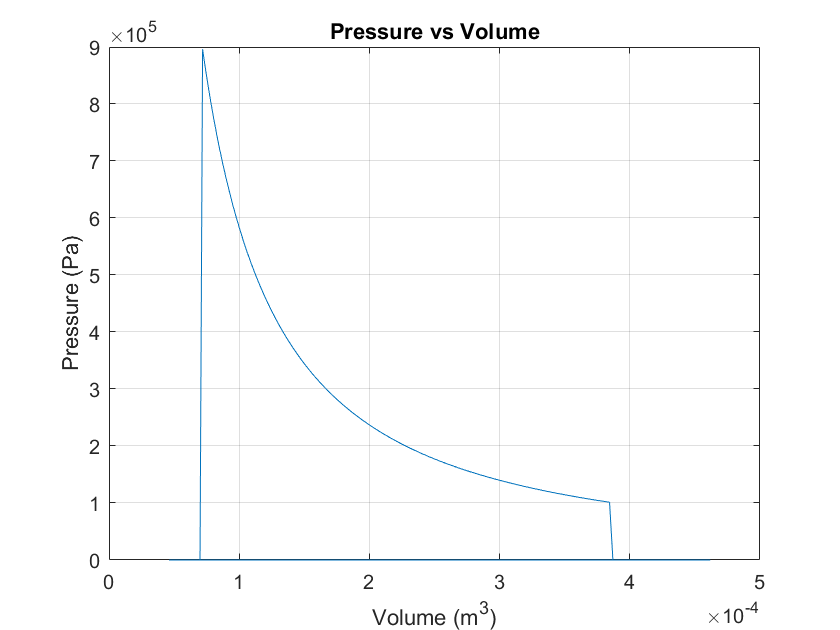

    temp(compression_start) = Taf; %degrees kelvin
    %% Compression Numerical Analysis
    mi = (p_atm * vol(compression_start)) / (R * temp(compression_start));
    mf = (mi) / (1 + AFR/phi);
    mass(1, compression_start:expansion_end) = mi;
    for i=(compression_start + 1):compression_end
        %%Calculating instanteneous pressure    
        pressure(i) = (p_atm*vol(compression_start)^yi) / (vol(i)^yi);

        %%Calculating temperature
        temp(i) = (pressure(i) * vol(i))/ (mi * R);
    end
    
    figure;  % Create a new figure window
plot(vol, pressure);
xlabel('Volume (m^3)');  % Label for x-axis
ylabel('Pressure (Pa)'); % Label for y-axis 
title('Pressure vs Volume'); % Title of the plot
grid on;  % Add grid for better readability

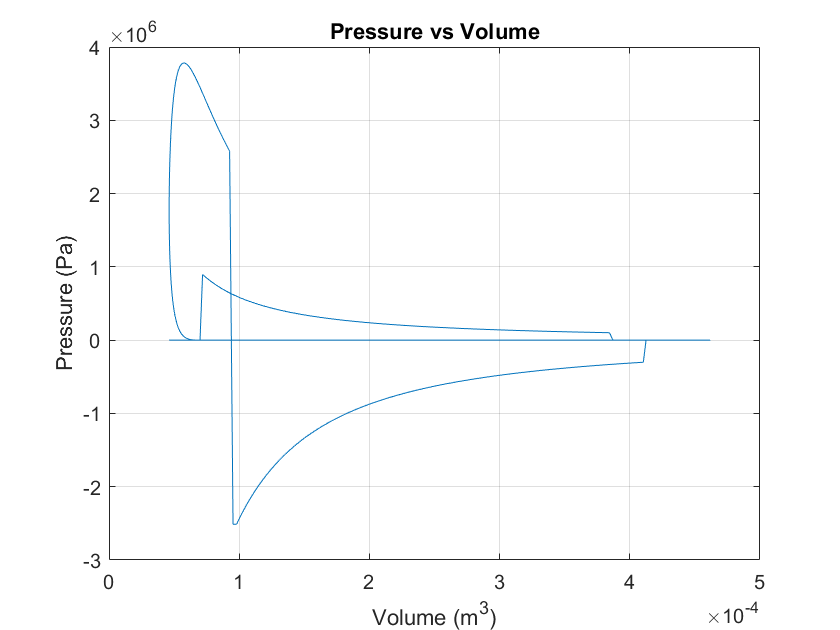

temp(combustion_start) = temp(compression_end);
temp(combustion_end) = (CBF * mf * Qhv)/(mi * cv) + temp(combustion_start);
pressure(combustion_end) = (mi * R * temp(combustion_end)) / (vol(combustion_end));
    for i=(combustion_start):(combustion_end - 1)
        xb(i) = 1- exp((-a)*((i-combustion_start)/(combustion_end - combustion_start))^(m+1));
        
        pressure(i) = ((xb(i) * ((pressure(combustion_end)*vol(combustion_end)^yc) - (pressure(combustion_start)*vol(combustion_start)^yc))) + (pressure(combustion_start)*vol(combustion_start)^yc))/(vol(i)^yc);
        pressure(i) = -1*pressure(i);
    end
    
        
figure;  % Create a new figure window
plot(vol, pressure);
xlabel('Volume (m^3)');  % Label for x-axis
ylabel('Pressure (Pa)'); % Label for y-axis 
title('Pressure vs Volume'); % Title of the plot
grid on;  % Add grid for better readability

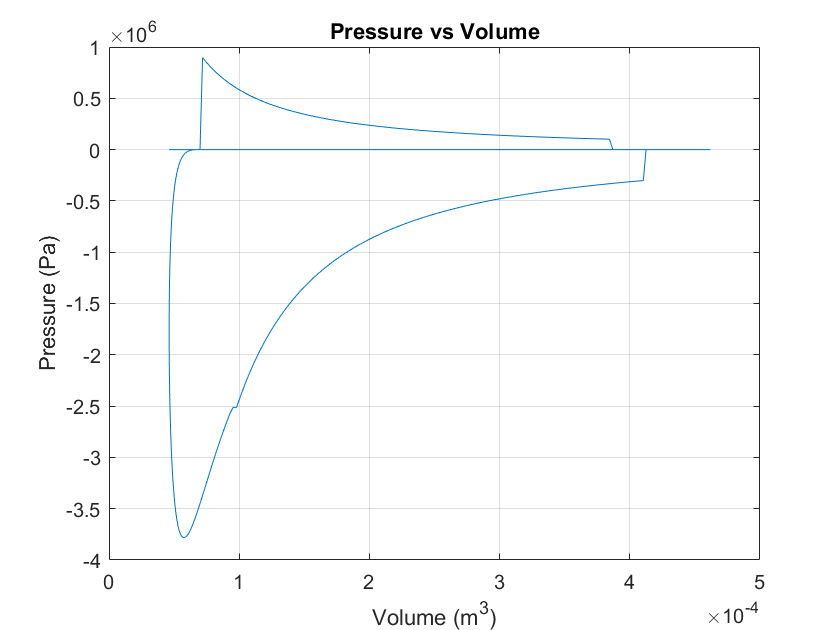

    %% Expansion Numerical Analysis
    pressure(expansion_start) = pressure(combustion_end);
    temp(expansion_start) = temp(combustion_end);
    for i=(expansion_start + 1):expansion_end
        %%Calculating instanteneous pressure
        pressure(i) = (pressure(expansion_start) * vol(expansion_start)^ye) / (vol(i)^ye);

        %%Calculating temperature
        temp(i) = (pressure(i) * vol(i))/ (mi * R);
    end
    
figure;  % Create a new figure window
plot(vol, pressure);
xlabel('Volume (m^3)');  % Label for x-axis
ylabel('Pressure (Pa)'); % Label for y-axis 
title('Pressure vs Volume'); % Title of the plot
grid on;  % Add grid for better readability